# PID Synthesis of Motor 1

T = 0.02;
z = tf('z', T);
s = tf('s');

Gpz = ((1.097*z^(2) + 0.008093*z - 0.1973)/(z^(3) - 1.073*z^(2) + 0.2992*z))

Gpz =
 
  1.097 z^2 + 0.008093 z - 0.1973
  -------------------------------
    z^3 - 1.073 z^2 + 0.2992 z
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


Gps = d2c(Gpz, 'tustin')

Gps =
 
  -0.3759 s^3 - 71.54 s^2 + 7085 s + 3.827e05
  -------------------------------------------
      s^3 + 159.1 s^2 + 6862 s + 9.535e04
 
Continuous-time transfer function.
Model Properties


Gps_FO = (4.01*exp(-0.0145*s))/(0.0405*s+1)

Gps_FO =
 
                       4.01
  exp(-0.0145*s) * ------------
                   0.0405 s + 1
 
Continuous-time transfer function.
Model Properties


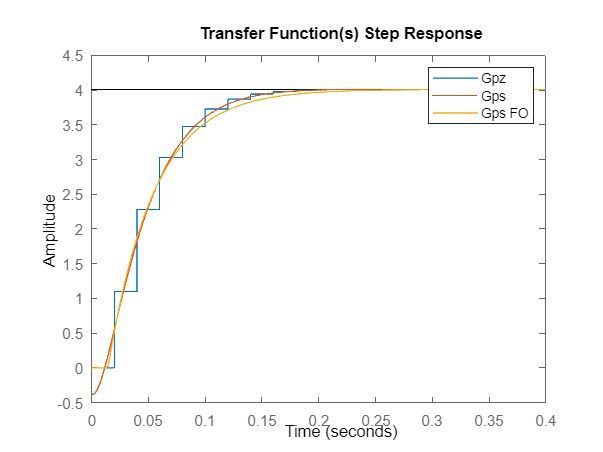

step(Gpz)
hold on
step(Gps)
step(Gps_FO)
legend('Gpz', 'Gps','Gps FO')
title('Transfer Function(s) Step Response')
hold off

For the the first order transfer function in continuous time, a two point analysis of the Motor 1 transfer function was made to determine the K, Tau and Theta values. 


$$\textrm{Gp}\left(s\right)=\frac{{\textrm{Ke}}^{\theta s} }{\tau s+1}$$



$$K=4\ldotp 01;$$



$$\tau =0\ldotp 0405;$$



$$\theta =0\ldotp 0145;$$


%Computing of the PID paramters (ITAE)
K = 4.01;
Tau = 0.0405;
Theta = 0.0145;

%ITAE
%{
a = 0.965;
b = -0.85;
c = 0.796;
d = -0.147;
e = 0.308;
f = 0.929;
%}
%IAE
a = 1.086;
b = -0.869;
c = 0.74;
d = -0.13;
e = 0.348;
f = 0.914;

Kp = (1/K)*(a*(Theta/Tau)^b);
Taui = (Tau)/(c+d*(Theta/Tau));
Taud = (Tau)*(e*(Theta/Tau)^f);

Kpz = Kp-(Kp*T)/(2*Taui)

Kpz = 0.5480

Kiz = (Kp*T)/Taui

Kiz = 0.2264

Kdz = (Kp*Taud)/T

Kdz = 0.1822